
myfolder = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma"

myfolder = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma"

filepattern_docu_table = fullfile(myfolder,"*.xlsx")

filepattern_docu_table = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/*.xlsx"

filepattern_supra = fullfile(myfolder,"*supra.txt")

filepattern_supra = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/*supra.txt"

filepattern_connectivity = fullfile(myfolder,"*connectivity.txt")

filepattern_connectivity = "/Users/emiliathoma/Desktop/docu_tables_und_traces_thoma/*connectivity.txt"


filelist_docu_table = dir(filepattern_docu_table);
filelist_supra = dir(filepattern_supra);
filelist_connectivity = dir(filepattern_connectivity);

all_data = struct;

### Einlesen docu_table

for k = 1:length(filelist_docu_table)
    basefilename = filelist_docu_table(k).name;
    fullfilename = fullfile(filelist_docu_table(k).folder, basefilename);
    thisDocuTable = readtable(fullfilename, "VariableNamingRule", "preserve");
    all_data(k).namen= basefilename;
    all_data(k).docutables = thisDocuTable;
end

for k = 1:length(filelist_supra)
    basefilename = filelist_supra(k).name;
    fullfilename = fullfile(filelist_supra(k).folder, basefilename);
    thisSupraTable = table2array(readtable(fullfilename, "VariableNamingRule", "preserve"));
    all_data(k).supra_namen= basefilename;
    all_data(k).supra = thisSupraTable;
    %supratables{k} = thisSupraTable
end


# tcell

variable_names_types = [["cell_ID", "string"]; ...
			["AP_Amplitude", "double"]; ...
			["half_duration_ms", "double"]; ...
			["type", "string"]; ...
            ["AP_time", "double"]; ...
            ["threshold_timpoint", "double"]; ...
            ["threshold_amplitude", "double"]; ...
            ["peak_amplitude", "double"]; ...
            ["freq_Hz_0ms_100ms", "double"]; ...
            ["Ap_number_0ms_100ms", "double"]; ...
            ["freq_Hz_200ms_400ms", "double"]; ...
            ["Ap_number_200ms_400ms", "double"]; ...
            ["input_resistance", "double"]; ...
            ["neutral_restingmembranepotential", "double"]; ...
            ["stim_restingmembranepotential", "double"]; ...
            ["downstroke_mVperms", "double"]; ...
            ["hyperpolarisation", "double"]; ...
            ["half_amplitude", "double"]];

% Make table using fieldnames & value types from above
tcell = table('Size',[0,size(variable_names_types,1)],... 
	'VariableNames', variable_names_types(:,1),...
	'VariableTypes', variable_names_types(:,2));


for i=1:size(all_data,2) %durch alle tables durch iterieren
    for channel_n = 1:10 %durch alle 10 channel iterieren
        if all_data(i).docutables{channel_n,2} ==1
            S=strsplit(all_data(i).supra_namen,"_");
            S=strjoin([S(2), S(3)],"_");
            length(tcell.cell_ID)+1
            cellID = append(S,"_C", string(channel_n)); %je nachdem welcher Manipulator ==1, also included war
            tcell.cell_ID(length(tcell.cell_ID)+1,1)=cellID;
        end
    end
end

ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 7

ans = 8

ans = 9

ans = 10

ans = 11

ans = 12

ans = 13

ans = 14

ans = 15

ans = 16

ans = 17

ans = 18

ans = 19

ans = 20

ans = 21

ans = 22

ans = 23

ans = 24

ans = 25

ans = 26

ans = 27

ans = 28

ans = 29

ans = 30

ans = 31

ans = 32

ans = 33

ans = 34

ans = 35

ans = 36

ans = 37

ans = 38

ans = 39

ans = 40

ans = 41

ans = 42

ans = 43

ans = 44

ans = 45

ans = 46

ans = 47

ans = 48

ans = 49

ans = 50

ans = 51

ans = 52

ans = 53

ans = 54

ans = 55

ans = 56

ans = 57

ans = 58

ans = 59

ans = 60

ans = 61

ans = 62

ans = 63

ans = 64

ans = 65

ans = 66

ans = 67

ans = 68

ans = 69

ans = 70

ans = 71

ans = 72

ans = 73

ans = 74

ans = 75

ans = 76

ans = 77


% stim_current_starts = [0.8e5, 1e5];
% stim_current = [-150e-12, -100e-12, -50e-12];
% Rin_sum=0;
% Rins={};
% for stim_i = 1: 3
% trace_segment = all_data(1).supra(stim_current_starts(1):stim_current_starts(2),5);
%             diff_trace_segment = diff(trace_segment);
%             diff_threshold = 2;
%             AP_time = find(diff_trace_segment>diff_threshold, 1, "first");
%             if isempty(AP_time)==1
%             steadystate=mean(trace_segment);
%             basesegment=(all_data(1).supra(stim_current_starts(1)-20000:stim_current_starts(2)-20000,5));
%             baseline=mean(basesegment);
%             end
% stim_starts = stim_current_starts + [0.4e5, 0.4e5];
% dV=steadystate-baseline
% Rin=(dV)*10^-3/stim_current(stim_i)
% Rins=[Rins, Rin]
% Rin_sum=Rin_sum+Rin
% end
% Rin_sum/stim_i
% Rins

% %to check each traces at the time for their firing pattern
% trace_segment = all_data(55).supra(:,5);                    
% 
% plot(trace_segment)


           % stim_starts = [4.8e5, 5e5];
            %if i==2 && channel_n==8
             %   stim_starts = [4.805e5, 5e5];
            %end
            %stim_duration = 1*20e3;
            %trace_segment = data(stim_starts(1):stim_starts(2),1);

            %diff_trace_segment = diff(trace_segment);
            %diff_threshold = 2;
            %AP_time = find(diff_trace_segment>diff_threshold, 1, "first")
           %    AP_time
            % figure
            % plot(trace_segment)
            % plot(diff_trace_segment, 'o')
            % Ap_number=1
            % First_AP_Time=AP_time
            % 
            % AP_time=AP_time+100
            % while AP_time<=2000
            %     freq_segment = data(stim_starts(1)+AP_time:stim_starts(2),1);
            %     stim_starts(1)+AP_time
            %     diff_freq_segment = diff(freq_segment);
            %     AP_time = AP_time+find(diff_freq_segment>diff_threshold, 1, "first")+100
            %     if isempty(AP_time) == 0
            %     Ap_number=Ap_number+1
            %     Last_AP_Time=AP_time-100
            %     end 
            % end
            % period = (Last_AP_Time-First_AP_Time)*0.00005
            % frq_per = Ap_number/period

k=1;
for i=1:size(all_data,2)
    for channel_n = 1:10 %durch alle 10 channel iterieren
        if all_data(i).docutables{channel_n,2} ==1
            data=all_data(i).supra(:,channel_n+1);
            stim_starts = [4.8e5, 5e5];
            stim_starts_before = [4.6e5, 4.8e5]; %to later test for freq in different stimulation timepoints
            stim_starts_after = [5e5, 5.2e5]; %to later test for freq in different stimulation timepoints
            %if i==2 && channel_n==8
            %    stim_starts = [4.805e5, 5e5];
            %end
            
            stim_duration = 1*20e3;
            trace_segment = data(stim_starts(1):stim_starts(2),1);
            % figure
            % plot(trace_segment)

            diff_trace_segment = diff(trace_segment);
            %downstroke in mV/ms
            max_downstroke_tik = min(diff_trace_segment);
            max_downstroke = max_downstroke_tik*20;
            try
            tcell.downstroke_mVperms(k)=max_downstroke;
    
            diff_threshold = 2;
            AP_time = find(diff_trace_segment>diff_threshold, 1, "first");
            
            
           
            % figure
            % % plot(diff_trace_segment, 'o')
            % % yline(2)
            % try
            % xline(AP_time)
            % end

            %extract the AP
            if AP_time < 50
            trace_AP = trace_segment(0:AP_time+100);
            else
            trace_AP = trace_segment(AP_time-50:AP_time+100);
            end
            tcell.AP_time(k)=AP_time;

            %threshold amplitude
            try
            threshold_timpoint = find(diff(trace_AP)>diff_threshold, 1, 'first');
            tcell.threshold_timpoint(k)=threshold_timpoint;
            threshold_amplitude = trace_AP(threshold_timpoint);
            tcell.threshold_amplitude(k)=threshold_amplitude;
            end

            %get the peak amplitude
            peak_amplitude = max(trace_AP);
            tcell.peak_amplitude(k) = peak_amplitude;

            %AP amplitude
            ap_amplitude = peak_amplitude-threshold_amplitude;
            tcell.AP_Amplitude(k)=ap_amplitude;

            %Hyperpolarisation
            try
            trace_AP_hyper_timeframe = trace_segment(AP_time-10:AP_time+100);
            hyperpolarisation = min(trace_AP_hyper_timeframe);
            tcell.hyperpolarisation(k)=hyperpolarisation;
            end

            %ap half duration:
            try
            half_amplitude = threshold_amplitude + (ap_amplitude/2);
            tcell.half_amplitude(k)=half_amplitude;
            first_crossing_of_half_amplitude = find(trace_AP>half_amplitude,1,"first");
            first_negative_crossing_of_half_amplitude = ...
                find(trace_AP(first_crossing_of_half_amplitude:end)<half_amplitude,1, "first") + first_crossing_of_half_amplitude;

            %half duration
            half_duration = first_negative_crossing_of_half_amplitude-first_crossing_of_half_amplitude;
            tcell.half_duration_ms(k)=half_duration/20;
            end
            end

            %resitingmembranepotential
            stim_starts_stimulus = [4.8e5, 5e5];
            stim_starts_anfang = [2.8e5, 3e5]
            rest_membranepot = (all_data(1).supra(stim_starts_stimulus(1)-20000:stim_starts_stimulus(2)-20000,channel_n+1));
            rest_pot_stim = mean(rest_membranepot)
            tcell.stim_restingmembranepotential(k)=rest_pot_stim
            rest_membranepot = (all_data(1).supra(stim_starts_anfang(1)-20000:stim_starts_anfang(2)-20000,channel_n+1));
            rest_pot_neutral = mean(rest_membranepot)
            tcell.neutral_restingmembranepotential(k)=rest_pot_neutral

            %input resistance
            stim_current_starts = [0.8e5, 1e5];
            stim_current = [-150e-12, -100e-12, -50e-12];
            Rin_sum=0;
            Rins={};
            Rin_avg=0;
            for stim_i = 1: 3
                trace_segment_res = all_data(i).supra(stim_current_starts(1):stim_current_starts(2),channel_n+1);
                diff_trace_segment_res = diff(trace_segment_res);
                diff_threshold = 2;
                AP_time_res = find(diff_trace_segment_res>diff_threshold, 1, "first");
                if isempty(AP_time_res)==1
                    steadystate=mean(trace_segment_res);
                    basesegment=(all_data(1).supra(stim_current_starts(1)-20000:stim_current_starts(2)-20000,channel_n+1));
                    baseline=mean(basesegment);
                end
                stim_current_starts = stim_current_starts + [0.4e5, 0.4e5];
                dV=steadystate-baseline;
                Rin=(dV)*10^-3/stim_current(stim_i);
                Rins=[Rins, Rin];
                Rin_sum=Rin_sum+Rin;
            end
            Rin_avg=Rin_sum/stim_i;
            %Tabele mit input resistances pro manip.
            Rins;
            tcell.input_resistance(k)=Rin_avg;
            %später in MegaOhmen angeben!!!


            %freq
            % figure
            % plot(trace_segment)

            try
            Ap_number=1;
            First_AP_Time=AP_time;

            AP_time_freq=AP_time+100;
            while AP_time_freq<=2000
                freq_segment = data(stim_starts(1)+AP_time_freq:stim_starts(2),1);
                stim_starts(1)+AP_time_freq;
                diff_freq_segment = diff(freq_segment);
                AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                if isempty(AP_time_freq) == 0 && AP_time_freq < 2000
                Ap_number=Ap_number+1;
                Last_AP_Time=AP_time_freq-100;
                end 
            end


            %tik in sekunde

            end
            try
            period = (Last_AP_Time-First_AP_Time)*0.00005;
            frq_per_0_100 = Ap_number/period;
            tcell.freq_Hz_0ms_100ms(k)=frq_per_0_100;
            tcell.Ap_number_0ms_100ms(k)= Ap_number;

            Ap_number=0; 
            AP_time_freq=4000;
            First_AP_Time=4000;
            while AP_time_freq<=8000
                 freq_segment = data(stim_starts(1)+AP_time_freq:stim_starts(2),1);
                 stim_starts(1)+AP_time_freq;
                 diff_freq_segment = diff(freq_segment);
                 AP_time_freq = AP_time_freq+find(diff_freq_segment>diff_threshold, 1, "first")+100;
                 if isempty(AP_time_freq) == 0 && AP_time_freq < 8000
                 Ap_number=Ap_number+1;
                 Last_AP_Time=AP_time_freq-100;
                 end 
             end
             period = (Last_AP_Time-First_AP_Time)*0.00005;
             frq_per_200_400 = Ap_number/period;
            tcell.freq_Hz_200ms_400ms(k)=frq_per_200_400;
            tcell.Ap_number_200ms_400ms(k)=Ap_number;
            end
            % figure
            % plot(trace_AP, "Color", "k", "LineWidth",2)
            %try
            %yline(threshold_amplitude)
            %xline(threshold_timpoint)
            %yline(peak_amplitude)
            %yline(half_amplitude)
            %xline(first_crossing_of_half_amplitude)
            %xline(first_negative_crossing_of_half_amplitude)   
            k=k+1
            
        end
    end
end 

stim_starts_anfang =       280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 2

stim_starts_anfang =       280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 3

stim_starts_anfang =       280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 4

stim_starts_anfang =       280000      300000


rest_pot_stim = -7.5336

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -8.1899

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 5

stim_starts_anfang =       280000      300000


rest_pot_stim = -7.1978

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -7.8904

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 6

stim_starts_anfang =       280000      300000


rest_pot_stim = -23.6789

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -23.7203

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 7

stim_starts_anfang =       280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 8

stim_starts_anfang =       280000      300000


rest_pot_stim = -7.5336

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -8.1899

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 9

stim_starts_anfang =       280000      300000


rest_pot_stim = -7.1978

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -7.8904

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 10

stim_starts_anfang =       280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 11

stim_starts_anfang =       280000      300000


rest_pot_stim = -7.1978

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -7.8904

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 12

stim_starts_anfang =       280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 13

stim_starts_anfang =       280000      300000


rest_pot_stim = -7.1978

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -7.8904

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 14

stim_starts_anfang =       280000      300000


rest_pot_stim = -23.6789

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -23.7203

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 15

stim_starts_anfang =       280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 16

stim_starts_anfang =       280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 17

stim_starts_anfang =       280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 18

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -7.5336

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -8.1899

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 19

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -7.1978

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -7.8904

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 20

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -23.6789

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -23.7203

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 21

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 22

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 23

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 24

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -7.5336

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -8.1899

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 25

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -7.1978

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -7.8904

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 26

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -23.6789

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -23.7203

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 27

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -7.1978

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -7.8904

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 28

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 29

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 30

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 31

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 32

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 33

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 34

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -7.5336

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -8.1899

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 35

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 36

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 37

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -7.1978

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -7.8904

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 38

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -23.6789

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -23.7203

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 39

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 40

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 41

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 42

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 43

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -23.6789

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -23.7203

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 44

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 45

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -23.6789

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -23.7203

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 46

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 47

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -23.6789

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -23.7203

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 48

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 49

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 50

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 51

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 52

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -7.1978

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -7.8904

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 53

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -23.6789

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -23.7203

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 54

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 55

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 56

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 57

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -7.5336

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -8.1899

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 58

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -7.1978

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -7.8904

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 59

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -23.6789

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -23.7203

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 60

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -7.1978

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -7.8904

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 61

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 62

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -7.5336

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -8.1899

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 63

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 64

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 65

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 66

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 67

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 68

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 69

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -7.1978

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -7.8904

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 70

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 71

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 72

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -64.5120

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -64.8885

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 73

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -7.5336

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -8.1899

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 74

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 75

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -7.5336

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -8.1899

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 76

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -23.6789

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -23.7203

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 77

stim_starts_anfang = 1×2
      280000      300000


rest_pot_stim = -44.4934

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

rest_pot_neutral = -45.8813

tcell = 77×18 table
         cell_ID         AP_Amplitude    half_duration_ms      type       AP_time    threshold_timpoint    threshold_amplitude    peak_amplitude    freq_Hz_0ms_100ms    Ap_number_0ms_100ms    freq_Hz_200ms_400ms    Ap_number_200ms_400ms    input_resistance    neutral_restingmembranepotential    stim_restingmembranepotential    downstroke_mVperms    hyperpolarisation    half_amplitude
    _________________    ____________    ________________    _________    _______    __________________    ___________________    ______________    

k = 78

writetable(tcell,"/Users/emiliathoma/Desktop/results_supra_rat.csv" )

data=all_data(27).supra(:,2)

data =   -31.0059
  -31.0974
  -30.7007
  -31.0059
  -31.1890
  -31.3416
  -30.8228
  -30.4565
  -30.8533
  -31.0669


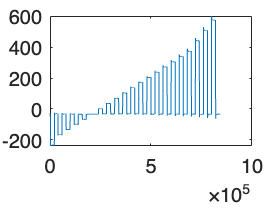

plot(data)

            stim_starts = [4.8e5, 5e5]

stim_starts =       480000      500000



            stim_duration = 1*20e3;
            trace_segment = data(stim_starts(1):stim_starts(2),1)

trace_segment =   -30.3040
  -31.0059
  -30.8533
  171.8140
  211.8835
  212.2498
  212.2192
  210.2356
  209.4727
  208.6487


            figure
            plot(trace_segment)


            diff_trace_segment = diff(trace_segment)

diff_trace_segment =    -0.7019
    0.1526
  202.6672
   40.0696
    0.3662
   -0.0305
   -1.9836
   -0.7629
   -0.8240
    0.7629


            %downstroke in mV/ms
            max_downstroke_tik = min(diff_trace_segment)

max_downstroke_tik = -5.1270

            max_downstroke = max_downstroke_tik*20

max_downstroke = -102.5391

            diff_threshold = 2

diff_threshold = 2

            AP_time = find(diff_trace_segment>diff_threshold, 1, "first")

AP_time = 3

% for k = 1:length(all_data.supra)
%     workingsupra = supratables{k}
%     for i = 2:11
% 
%         %Stimulation time points:
%         stim_starts = [4.2e5, 4.4e5];
%         stim_duration = 1*20e3;
% 
%         for stim_number=1:size(stim_starts,2)
%             trace_segment = workingsupra(stim_starts(stim_number):stim_starts(stim_number)+stim_duration,[1,i]);
%             figure
%             name = string(fieldnames(trace_segment))
% 
%             plot(trace_segment,"s",name(2))
%             diff_trace_segment = diff(trace_segment.(name(2)));
% 
%             %detect action potential when derivative exceeds
%             diff_threshold = 2;
%             AP_index = find(diff_trace_segment>diff_threshold, 1, "first")
%             AP_time = table2array(trace_segment(AP_index,1))
% 
%             figure
%             plot(diff_trace_segment, 'o')
%             yline(2)
%             try
%             xline(AP_time)
%             end
% 
%             %extract the AP
%             try
%             trace_AP = trace_segment(AP_index-50:AP_index+100,name(2))
%             diff_AP_segment = diff(trace_AP.(name(2)));
% 
%             %Get the first values to publish in my paper:
%             %threshold amplitude
%             threshold_timpoint = find(diff_AP_segment>diff_threshold, 1, 'first')
%             threshold_amplitude = table2array(trace_AP(threshold_timpoint, name(2)))
%             %get the peak amplitude
%             peak_amplitude = table2array(max(trace_AP(:, name(2))))
%             %AP amplitude
%             ap_amplitude = peak_amplitude-threshold_amplitude
%             %ap half duration
%             half_amplitude = threshold_amplitude + (ap_amplitude/2)
%             first_crossing_of_half_amplitude = find(table2array(trace_AP)>half_amplitude,1,"first")
%             AP_array = table2array(trace_AP)
%             first_negative_crossing_of_half_amplitude = find((AP_array(first_crossing_of_half_amplitude:end))<half_amplitude,1, "first") + first_crossing_of_half_amplitude
%             half_duration = first_negative_crossing_of_half_amplitude-first_crossing_of_half_amplitude
% 
%             trace_AP.s=table2array(trace_segment((AP_index-50:AP_index+100),"s"))
%             figure
%             plot(trace_AP, "s",name(2))
%             try
%             yline(threshold_amplitude)
%             xline(traceAP(threshold_timpoint:"s"))
%             yline(peak_amplitude)
%             yline(half_amplitude)
%             xline(traceAP(first_crossing_of_half_amplitude:"s"))
%             xline(traceAP(first_negative_crossing_of_half_amplitude:"s"))
%             end
%             k=k+1
%             end
% % end
% 
% 
% 
%     end
% end

writetable(tcell,"/Users/emiliathoma/Desktop/results_supra_rat_stim_350pA.csv" )
